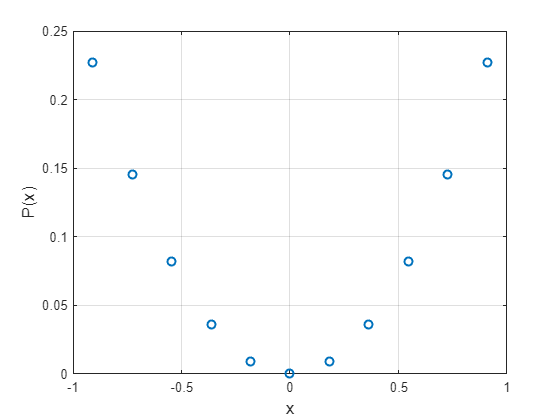

% ----------------------------------------------
% This program formulates the minimimal variance mechanism problem into a
% linear programing problem, and solves it using the built-in solver in Matlab.
% Comments are adquent in the code. 
% If you have any question,
% please feel free to contact Fei Wei at feiwei@nus.edu.sg
% ----------------------------------------------

close all
clear

% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 2; %the ratio amax/(xmax-xmin)

xmax = 1;
N = 11; % Total number of bins in [-xmax,xmax]
x_bin_size = 2*xmax/N;
x_grid = linspace(-xmax+0.5*x_bin_size,xmax-0.5*x_bin_size,N);

% We assign a distribution to X\in x_grid
% In the write-up, this is the data distribution

% x_P = ones(1,N)/N; % Uniform distribution

x_P = x_grid.^2;
x_P = x_P./ sum(x_P);

% x_P = x_grid-min(x_grid);
% x_P = x_P./sum(x_P);

figure
plot(x_grid,x_P,'o',LineWidth=1.5);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on


% [totalVariance,pMatrix] = opt_variance(eps,r,axRatio,x_grid,x_P);

% For testing, we sample a sequence of epsilon values
eps_grid = exp(linspace(0,log(8),20));

% The variance of optimal mechanism
VarOpt = zeros(1,length(eps_grid));
VarOptWorst = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    [varVector,pMatrix,a_grid] =... 
        opt_variance(eps_grid(i),delta,r,axRatio,x_grid,x_P);
    VarOpt(i) = x_P*varVector;
    VarOptWorst(i) = max(varVector);
end

--------------------------------
eps = 1.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.3481   -0.0715   -0.0555   -0.0850    0.0997    0.2220    0.0274   -0.4242    0.6106    0.3179    0.1059


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     2.2862    2.3609    2.3365    2.2726    2.2771    3.4176    2.2771    2.2726    2.3365    2.3609    2.2862


--------------------------------
eps = 1.115658, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

    0.0081   -0.0307    0.0833    0.0049    0.0128   -0.0111   -0.0109   -0.0025    0.0278   -0.0348   -0.1322


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     2.0490    2.0169    1.9361    1.9594    2.0432    3.0600    2.0432    1.9594    1.9361    2.0169    2.0490


--------------------------------
eps = 1.244693, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-14 *

    0.0047    0.1618    0.0111   -0.0007   -0.0015   -0.0222    0.0007    0.0228    0.0125   -0.0355    0.0289


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.7821    1.6784    1.5658    1.7232    1.8102    2.6287    1.8102    1.7232    1.5658    1.6784    1.7821


--------------------------------
eps = 1.388651, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.5263    0.2997   -0.2220    0.0155   -0.0475    0.1110   -0.1273    0.1096    0.0555   -0.3314    0.0507


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.4864    1.3518    1.4078    1.5562    1.6305    2.0828    1.6305    1.5562    1.4078    1.3518    1.4864


--------------------------------
eps = 1.549260, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.2418   -0.2678   -0.5759   -0.1399    0.1345         0    0.1024    0.0124   -0.8882    0.3644   -0.0193


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.2538    1.0606    1.1446    1.2867    1.3577    1.6261    1.3577    1.2867    1.1446    1.0606    1.2538


--------------------------------
eps = 1.728444, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.7208    0.0768    0.0625    0.0798    0.1713   -0.1110   -0.0846    0.0853   -0.0625   -0.0859    0.2925


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     1.0467    0.8393    0.8773    1.0176    1.1205    1.6173    1.1205    1.0176    0.8773    0.8393    1.0467


--------------------------------
eps = 1.928352, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.1569   -0.0608    0.2689    0.3972    0.0017    0.0555   -0.0136   -0.0811   -0.1561   -0.1797    0.0090


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.7778    0.7161    0.7299    0.8631    0.9627    1.2015    0.9627    0.8631    0.7299    0.7161    0.7778


--------------------------------
eps = 2.151381, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0931    0.0088    0.0421    0.0380    0.0450    0.1665   -0.0515   -0.0546    0.0625   -0.0425    0.0852


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.5933    0.5698    0.5808    0.5979    0.6971    0.9321    0.6971    0.5979    0.5808    0.5698    0.5933


--------------------------------
eps = 2.400205, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0711   -0.1180    0.0142   -0.0243    0.0382         0   -0.0624    0.0035    0.0208   -0.0423   -0.0346


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.4486    0.4239    0.4652    0.4982    0.5643    0.6960    0.5643    0.4982    0.4652    0.4239    0.4486


--------------------------------
eps = 2.677808, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0033    0.0193    0.0195    0.0431    0.2115         0   -0.2578   -0.0046    0.0642   -0.0171   -0.0557


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.3322    0.3257    0.3588    0.3918    0.4037    0.6527    0.4037    0.3918    0.3588    0.3257    0.3322


--------------------------------
eps = 2.987518, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.1648   -0.9144   -0.1850   -0.5478    0.0810         0    0.2639    0.3128   -0.1209   -0.0347   -0.4657


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.2637    0.2341    0.2396    0.2726    0.3009    0.6934    0.3009    0.2726    0.2396    0.2341    0.2637


--------------------------------
eps = 3.333048, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0293    0.0136   -0.0024    0.0245   -0.0025    0.2776    0.0024    0.0144    0.0215   -0.0057   -0.0347


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.1827    0.1827    0.1785    0.2115    0.2342    0.8778    0.2342    0.2115    0.1785    0.1827    0.1827


--------------------------------
eps = 3.718541, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

    0.0160   -0.0004   -0.0163   -0.0074    0.1368    0.2220   -0.0138    0.0015    0.0146   -0.0106   -0.0312


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.1339    0.1339    0.1235    0.1235    0.1539    0.9604    0.1539    0.1235    0.1235    0.1339    0.1339


--------------------------------
eps = 4.148620, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.0525    0.0093    0.0494   -0.2546   -0.8195         0    0.1591   -0.1275    0.0685   -0.0777   -0.0173


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0910    0.0957    0.0852    0.0852    0.1514    0.9175    0.1514    0.0852    0.0852    0.0957    0.0910


--------------------------------
eps = 4.628441, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

   -0.1035    0.3426   -0.0891    0.0706   -0.0408    0.5551   -0.1471    0.6963   -0.0903    0.0315    0.0043


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0601    0.0710    0.0710    0.0486    0.0817    0.8865    0.0817    0.0486    0.0710    0.0710    0.0601


--------------------------------
eps = 5.163757, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.0835    0.0121   -0.0072    0.0540   -0.0295    0.1665   -0.0105   -0.0142   -0.0148    0.0060   -0.0189


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.0397    0.0487    0.0409    0.0409    0.0740    0.8661    0.0740    0.0409    0.0409    0.0487    0.0397


--------------------------------
eps = 5.760986, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-16 *

    0.0267   -0.0094    0.0785   -0.1505    0.1135    0.5551   -0.1615    0.2953    0.0729   -0.0040   -0.0423


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×11
    0.0274    0.0214    0.0386    0.0277    0.0571    0.8539    0.0571    0.0277    0.0386    0.0214    0.0274


--------------------------------
eps = 6.427290, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×11
1.0e-16 *

    0.0207   -0.0167    0.0089    0.0059    0.0319    0.5551   -0.6273   -0.0001    0.0007   -0.0069    0.0198


Distribution validity check (should be all ones):


ans = 1×11
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×11
    0.0187    0.0144    0.0109    0.0083    0.0387    0.8452    0.0387    0.0083    0.0109    0.0144    0.0187


--------------------------------
eps = 7.170657, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×11
1.0e-16 *

   -0.0118   -0.0072   -0.0017   -0.0009   -0.3073    0.5551    0.3015    0.0036   -0.0085    0.0079    0.3974


Distribution validity check (should be all ones):


ans = 1×11
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×11
    0.0091    0.0070    0.0053    0.0040    0.0358    0.8355    0.0358    0.0040    0.0053    0.0070    0.0091


--------------------------------
eps = 8.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1×11
1.0e-15 *

   -0.0005    0.0004    0.0004   -0.0001    0.0001    0.3886    0.0003   -0.0001   -0.0002   -0.0007    0.0003


Distribution validity check (should be all ones):


ans = 1×11
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans = 1×11
    0.0045    0.0034    0.0025    0.0019    0.0014    0.8310    0.0014    0.0019    0.0025    0.0034    0.0045


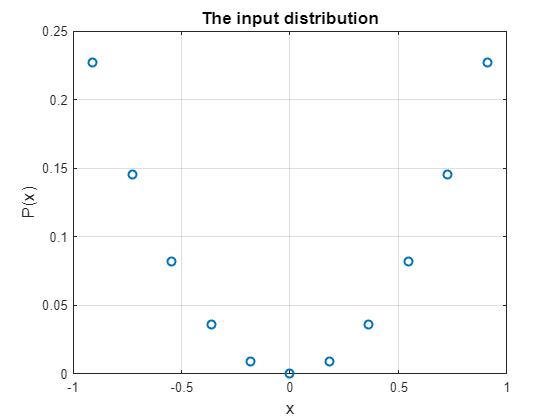

% The variance vector of Laplace mechanism
VarLaplace = zeros(1,length(eps_grid));
for i = 1:length(eps_grid)
    VarLaplace(i) = 8/(eps_grid(i))^2;
end

% The variance vector of Duchi mechanism
VarDuchi = zeros(1,length(eps_grid));
VarDuchiWorst = zeros(1,length(eps_grid));
var_duchi = @(ti,eps) ((exp(eps)+1)/(exp(eps)-1)).^2 - ti.^2;
for i = 1:length(eps_grid)
    temp = var_duchi(x_grid,eps_grid(i));
    VarDuchi(i) = temp *x_P';
    VarDuchiWorst(i) = max(temp);
end

% The variance vector of piece-wise mechanism
VarPiecewise = zeros(1,length(eps_grid));
VarPiecewiseWorst = zeros(1,length(eps_grid));
var_piecewise = @(ti,eps) ti.^2./(exp(eps/2)-1) + (exp(eps/2)+3)/3/(exp(eps/2)-1)^2;
for i = 1:length(eps_grid)
    temp = var_piecewise(x_grid,eps_grid(i));
    VarPiecewise(i) = temp *x_P';
    VarPiecewiseWorst(i) = max(temp);
end

% The variance vector of Hybrid mechanism
VarHybrid = zeros(1,length(eps_grid));
VarHybridWorst = zeros(1,length(eps_grid));
alpha = @(eps) sign(max(eps-0.61,0))*(1-exp(-eps/2));
var_hybrid = @(ti,eps) alpha(eps)*var_piecewise(ti,eps) + (1-alpha(eps))*var_duchi(ti,eps);
for i = 1:length(eps_grid)
    temp = var_hybrid(x_grid,eps_grid(i));
    VarHybrid(i) = temp *x_P';
    VarHybridWorst(i) = max(temp);
end

% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",FontSize=13);
xlabel("x",FontSize=13);
ylabel("P(x)",FontSize=13);
grid on

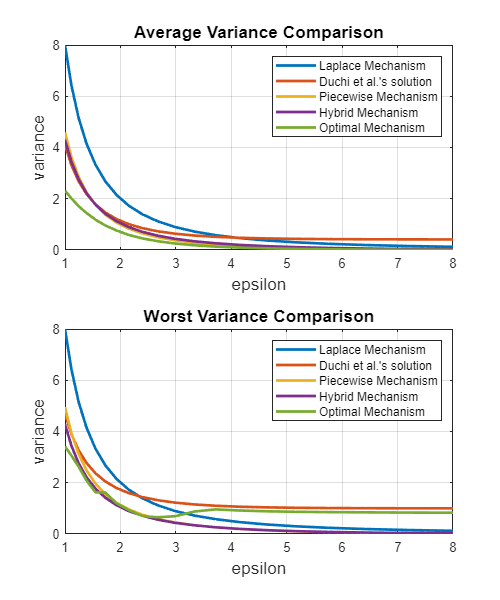


figure;
f = figure;
f.Position = [0 0 500 600];

subplot(2,1,1)
plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchi,LineWidth=2);
hold on
plot(eps_grid,VarPiecewise,LineWidth=2);
hold on
plot(eps_grid,VarHybrid,LineWidth=2);
hold on
plot(eps_grid,VarOpt,LineWidth=2);

title("Average Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

subplot(2,1,2)
plot(eps_grid,VarLaplace,LineWidth=2);
hold on
plot(eps_grid,VarDuchiWorst,LineWidth=2);
hold on
plot(eps_grid,VarPiecewiseWorst,LineWidth=2);
hold on
plot(eps_grid,VarHybridWorst,LineWidth=2);
hold on
plot(eps_grid,VarOptWorst,LineWidth=2);
title("Worst Variance Comparison",FontSize=13)
xlabel("epsilon",FontSize=13)
ylabel("variance",FontSize=13)
legend("Laplace Mechanism", "Duchi et al.'s solution",...
    "Piecewise Mechanism","Hybrid Mechanism","Optimal Mechanism")
grid on

% Please be advised this section is another experiment.

q = 10; % quantization level
% eps = 2; % privacy parameter
delta = 0; % privacy parameter
r=0.5; % geometric series constant
axRatio = 4; %the ratio amax/xmax
eps = 2; % the privacy parameter


xmax = 1;
M = 11; % Total number of bins in [-xmax,xmax]
x_bin_size = 2*xmax/M;
x_grid = linspace(-xmax+0.5*x_bin_size,xmax-0.5*x_bin_size,M);

% xmax = 1;
% xmax = floor(xmax*q)/q; % We need to make sure they are integers
% M = 2*xmax*q+1; % total amount of x samples
% x_grid = linspace(-xmax,xmax,M);

% We assign a distribution to X\in x_grid

x_P = ones(1,M)/M; % Uniform distribution

% x_P = x_grid.^2;
% x_P = x_P./ sum(x_P);

% x_P = x_grid-min(x_grid);
% x_P = x_P./sum(x_P);

[varVector,pMatrix,a_grid] =...
    opt_variance(eps,delta,r,axRatio,x_grid,x_P);

--------------------------------
eps = 2.000000, delta = 0.000000

Optimal solution found.

Expectations validity check (should be all zeros):
 

ans = 1.0e-15 *

   -0.2603   -0.0950   -0.2166   -0.0134   -0.0023   -0.1943   -0.0103         0   -0.1153   -0.0761   -0.1952


Distribution validity check (should be all ones):


ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Variance vector:


ans =     0.8108    0.7446    0.6855    0.6194    0.5401    0.4410    0.5401    0.6194    0.6855    0.7446    0.8108


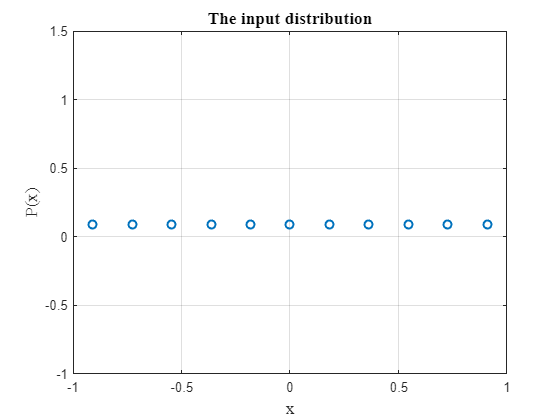

% The plots

figure;
plot(x_grid,x_P,'o',LineWidth=1.5);
title("The input distribution",'FontSize',13,'FontName','Times');
xlabel("x",'FontSize',13,'FontName','Times');
ylabel("P(x)",'FontSize',13,'FontName','Times');
grid on

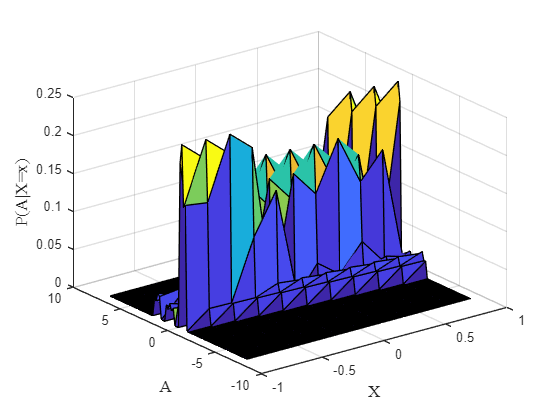


figure
[X_grid,Y_grid] = meshgrid(-x_grid,a_grid);
surf(X_grid,Y_grid,pMatrix');
xlabel("X",'FontSize',13,'FontName','Times');
ylabel("A",'FontSize',13,'FontName','Times');
zlabel("P(A|X=x)",'FontSize',13,'FontName','Times');